# Basic Gravity Columns

This notebook covers the basic functionalities of simulating basic gravity column models, using different reservoirs. Beisdes clearing the variable in the workspace, as previous examples, this section clears the variables and sets up the incomp module needed for these systems. Moreover, the gravity and fluid properties are also set.

clear;
mrstModule add incomp
gravity reset on
fluid = initSingleFluid('mu', 1*centi*poise, 'rho', 1014*kilogram/meter^3);

## Rectangular grid

In this case, let us set a basic rectangular grid, using uniform rock properties:

G = cartGrid([40, 40, 40], [40, 40, 40]);
G = computeGeometry(G);

rock = makeRock(G, 100*milli*darcy, 0.2);

In the gravity column example, we must set a boundary condition, which can be a topside or bottomhole pressure. In the following code, we set a topside pressure of 100 bar, for example:

P = 100;
bc = pside([], G, 'TOP', P*barsa());

We need the following elements to solve the system: grid, rock, fluid. The first two are used for the transmissibility matrix. Additional parameters like wells, sources, and boundary conditions are included as keyword arguments:

T = computeTrans(G, rock);
sol = incompTPFA(initResSol(G, 0.0), G, T, fluid, 'bc', bc);

With our solution at hand, we can plot the face pressures of the system and see the pressure distribution according to gravity:

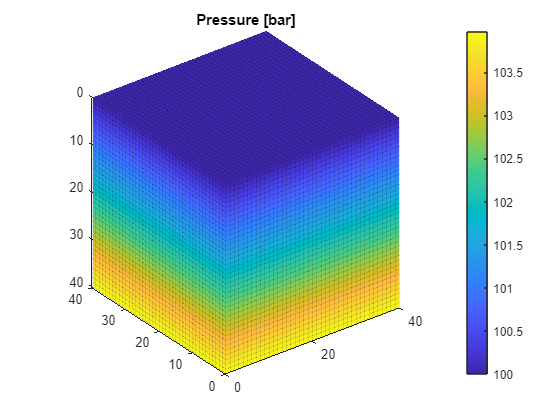

clf;
plotFaces(G, 1:G.faces.num, convertTo(sol.facePressure, barsa()), 'EdgeAlpha', 0.1);
set(gca, 'ZDir', 'reverse'), title('Pressure [bar]')
view(3), colorbar, axis equal

## Spherical Grid

We can use the same procedure to simulate a spherical reservoir. First, carve the sphere out and set rock properties:

radius = 10;
c = G.cells.centroids;
criteria = sqrt((c(:,1) - (40/2)).^2 + (c(:,2) - (40/2)).^2 + (c(:,3) - (40/2)).^2);
G_sphere = removeCells(G, criteria>radius);
G_sphere = computeGeometry(G_sphere);
rock_sphere = makeRock(G_sphere, 100*milli*darcy, 0.2);

Afterwards, the process is the same: set boundary conditions, solve and plot:

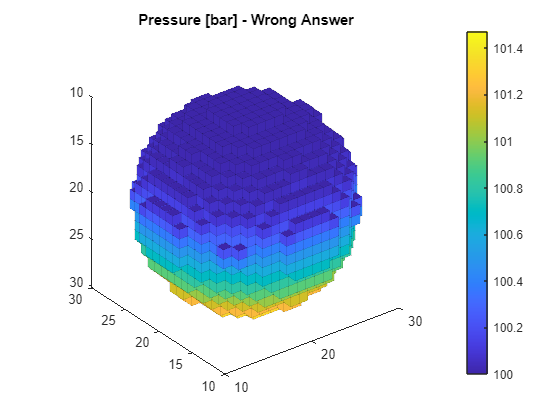

P = 100;
bc = pside([], G_sphere, 'TOP', P*barsa());
T = computeTrans(G_sphere, rock_sphere);
sol = incompTPFA(initResSol(G_sphere, 0.0), G_sphere, T, fluid, 'bc', bc);
clf;
plotFaces(G_sphere, 1:G_sphere.faces.num, convertTo(sol.facePressure, barsa()), 'EdgeAlpha', 0.1);
set(gca, 'ZDir', 'reverse'), title('Pressure [bar] - Wrong Answer')
view(3), colorbar, axis equal

This result is, however, visually inaccurate, and not coherent. This is because the boundary condition is applied to all faces on the top, were in reality it should only be applied to some, the ones at the very top of the sphere. To correct this, we must change how to set the boundary conditions.

To do so, we must get all the face centroids, and select the faces which match the lowest centroids. This generic approach works with any orthogonal geometry.

faces = 1:G_sphere.faces.num;
face_criteria = G_sphere.faces.centroids(:,3)<=(min(G_sphere.faces.centroids(:,3)));
faces = faces(face_criteria);
P = 100;
bc = addBC([],faces,'pressure',P*barsa());

With these changes, we can redo the solution and plot, to find the new result to be coherent.

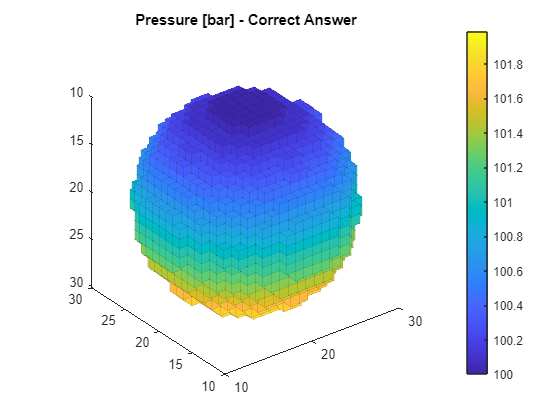

T = computeTrans(G_sphere, rock_sphere);
sol = incompTPFA(initResSol(G_sphere, 0.0), G_sphere, T, fluid, 'bc', bc);
clf;
plotFaces(G_sphere, 1:G_sphere.faces.num, convertTo(sol.facePressure, barsa()), 'EdgeAlpha', 0.1);
set(gca, 'ZDir', 'reverse'), title('Pressure [bar] - Correct Answer')
view(3), colorbar, axis equal

## Normal Intersection Grid

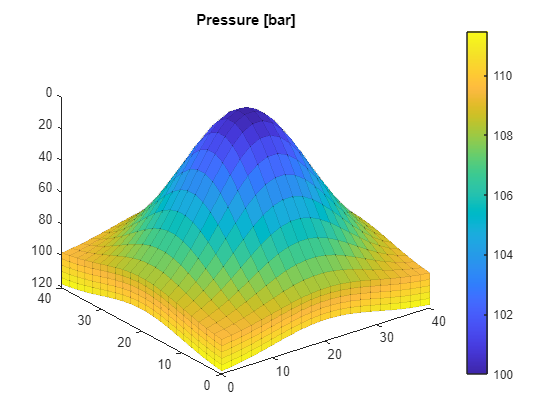

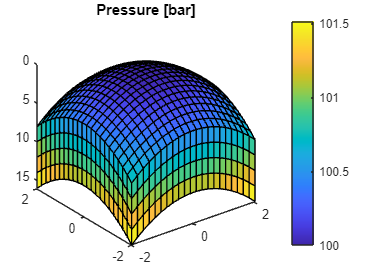

len = 40;
num_cell = 20;
range = 0:(len/num_cell):len;
x = range';
y = range;
for i = 1:(length(range) - 1)
    x = [x range'];
    y = [y; range];
end

nd = 100;

z = zeros(length(range));

for i = 1:(length(range))
    for j = 1:(length(range))
        z(i, j) = -nd*exp(-((x(i, j) - 20)^2 + (y(i, j) - 20)^2)/200);
    end
end

thickness = 20;
number_of_layers = 5;

horizons = {struct('x',x,'y',y,'z',z + 100),struct('x',x,'y',y,'z',z + 100 + thickness)};
grdecl = convertHorizonsToGrid(horizons,'layers', number_of_layers);
G_horizon = processGRDECL(grdecl);
G_horizon = computeGeometry(G_horizon);
rock_horizon = makeRock(G_horizon, 100*milli*darcy, 0.2);
faces = 1:G_horizon.faces.num;
face_criteria = G_horizon.faces.centroids(:,3)<=(min(G_horizon.faces.centroids(:,3)));
faces = faces(face_criteria);
P = 100;
bc = addBC([],faces,'pressure',P*barsa());

T = computeTrans(G_horizon, rock_horizon);
sol = incompTPFA(initResSol(G_horizon, 0.0), G_horizon, T, fluid, 'bc', bc);
clf;
plotFaces(G_horizon, 1:G_horizon.faces.num, convertTo(sol.facePressure, barsa()), 'EdgeAlpha', 0.1);
set(gca, 'ZDir', 'reverse'), title('Pressure [bar]')
view(3), colorbar